Toolboxes used in this Live Script:

•    Image Processing Toolbox

•    Computer Vision Toolbox

The pupose of detecting features is to provide a fingerprint of pictures as well as fixed points to track on the image to be able to determine, for example, how an image, or the camera has moved. An example of this application would be a computer vision system for a car, which needs to find out its speed by calculating how quickly a stop sign is approaching.

The output of the camera is a very fast stream of images (basically a video) and the relevant features must be extracted and matched to those of the features in previous images in teh time it takes for the next picture to arrive. Furthermore, the algorithm needs to be robust and be able to identify the same feature in different images even if it has changed position, rotation or scale. 

The Harris Detector is fairly robust, it can still detect features if they have translated or rotated as can be seen here:

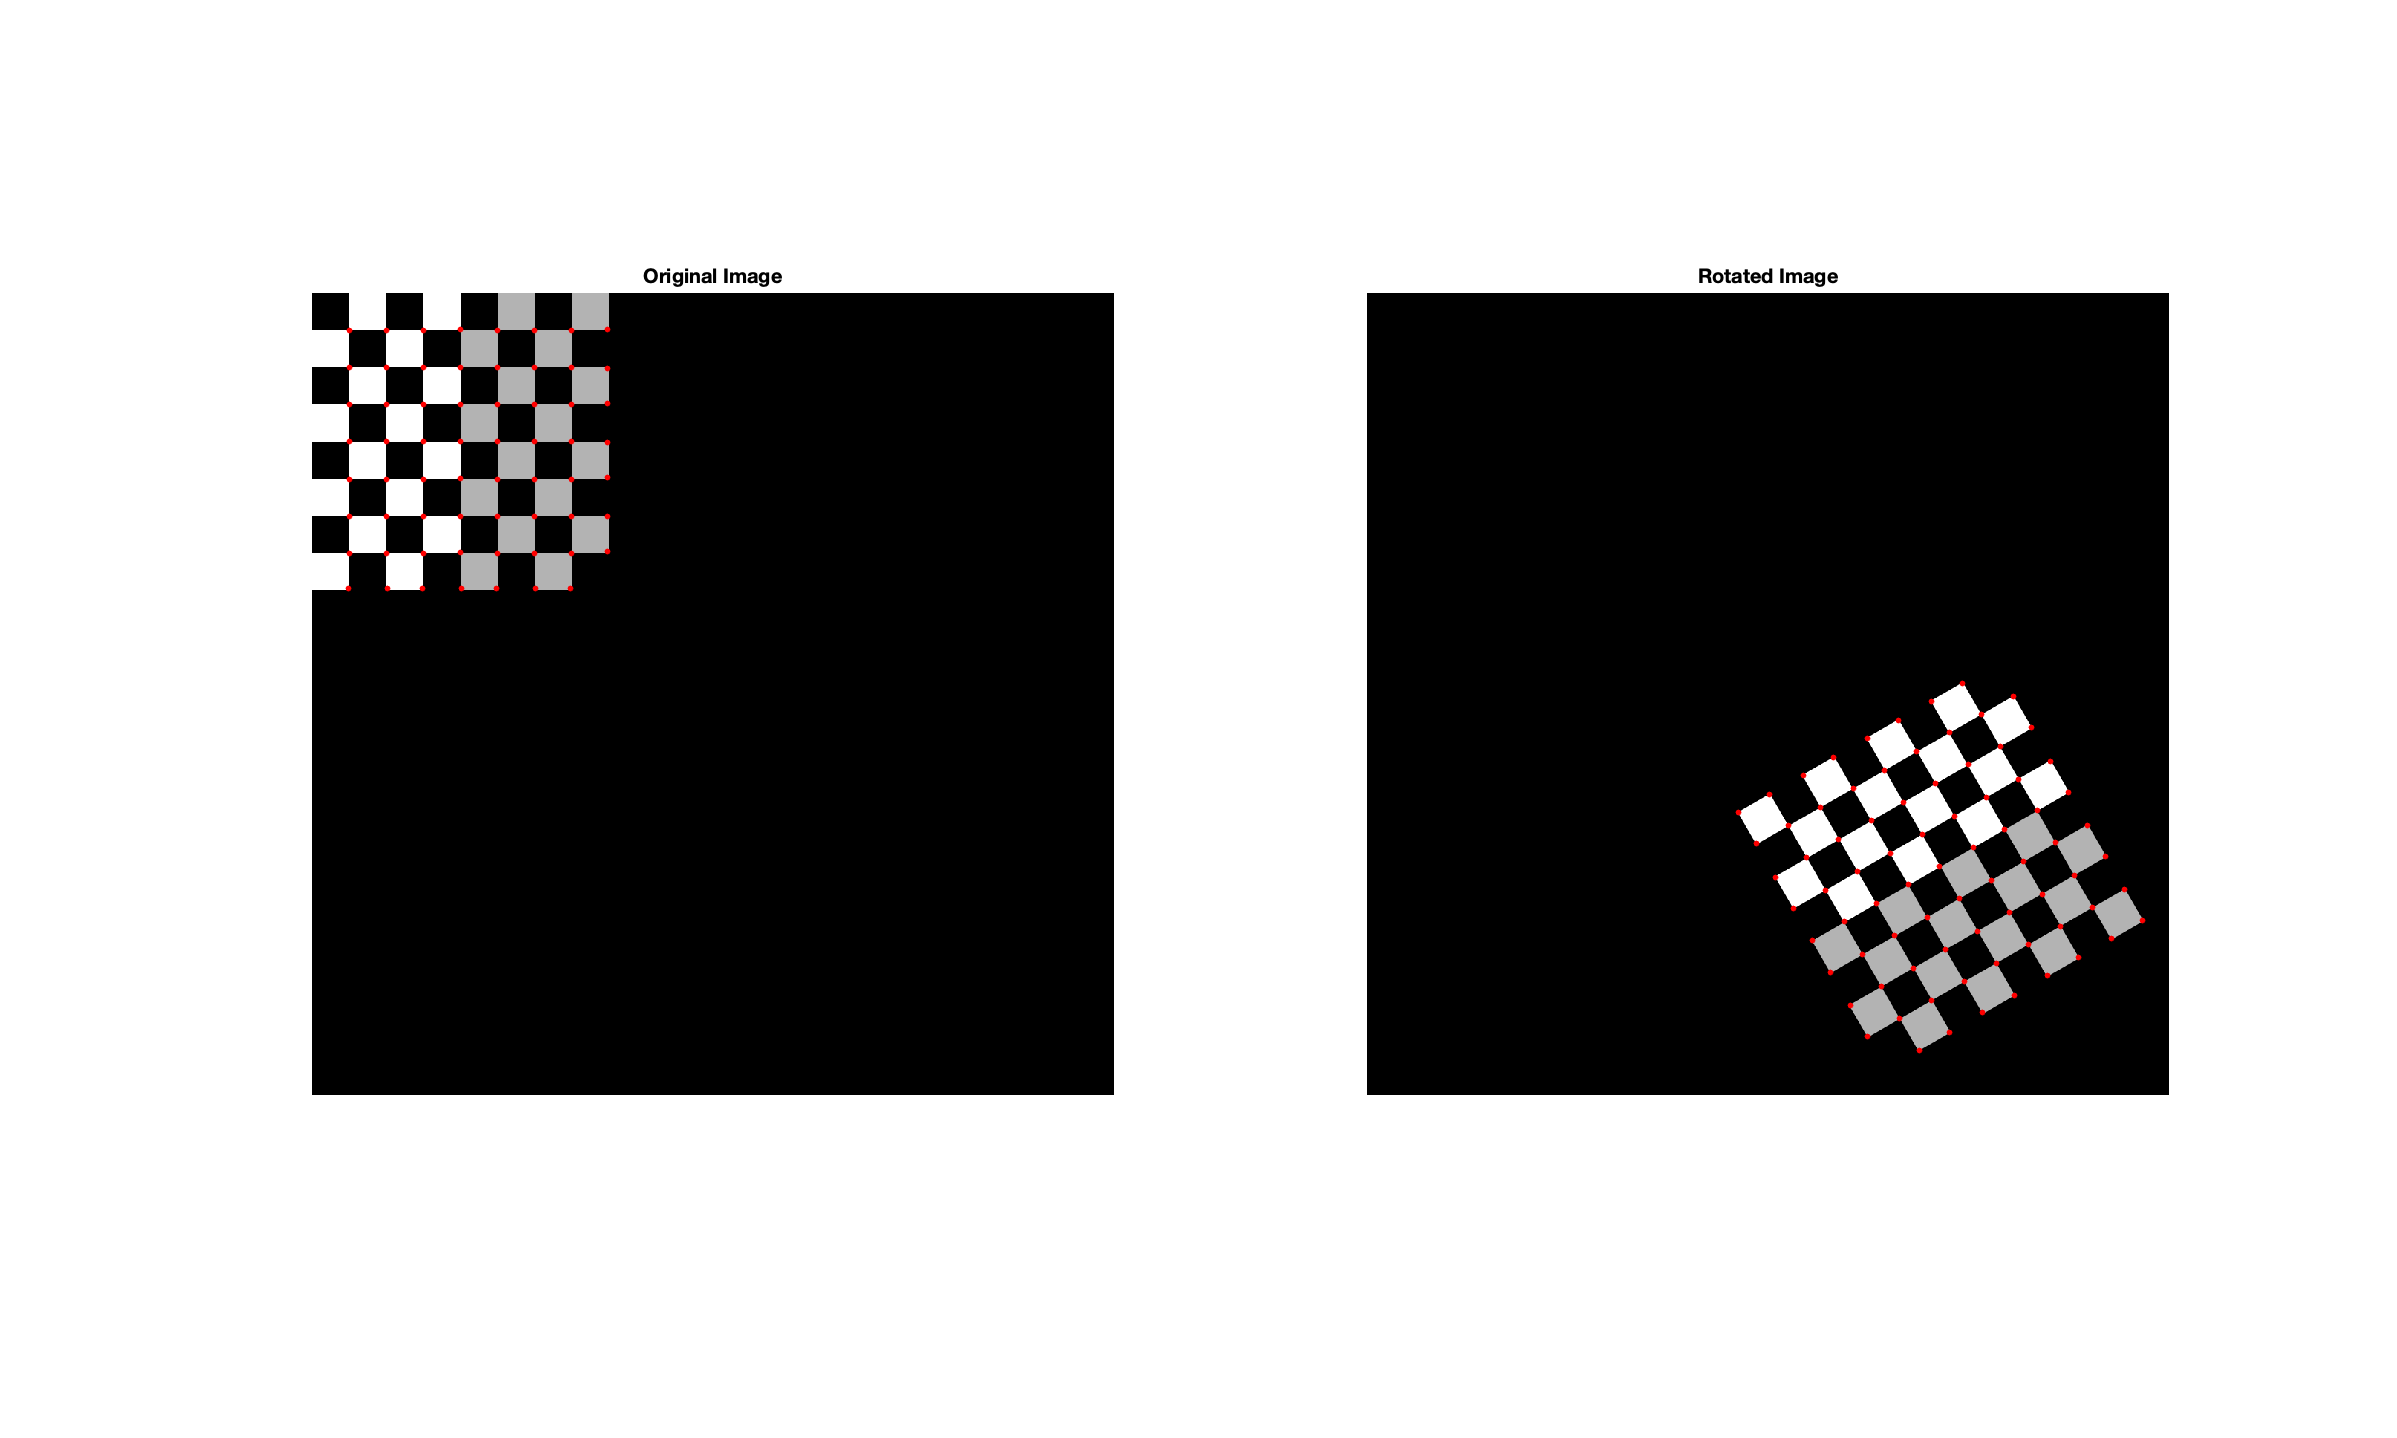

%%CHANGE TRANSLATION AND ROTATION HERE:
translation_x=500;
translation_y=500;
rotation=-60;

orig_image=zeros(1080);
rot_image=zeros(1080);

checkers=checkerboard(50);
checkers_rot=imrotate(checkers,rotation,'bilinear','loose');

orig_image(1:size(checkers,1),1:size(checkers,2))=checkers;
rot_image(translation_y:translation_y+size(checkers_rot,1)-1,translation_x:translation_x+size(checkers_rot,2)-1) = checkers_rot;

corners = uint16(detectHarrisFeatures(orig_image).Location);
checkers_rot_corners = uint16(detectHarrisFeatures(rot_image).Location); 
% The location of the corners will be used as index for the image, therefore the conversion to uint16

figure
set(gcf,'position',[0,0,3000,1800]);
subplot(1,2,1) 
imshow(orig_image,[])
title1=title('Original Image');
title1.FontSize=20;
hold on % show what comes next in the same subplot
scatter(corners(:,1),corners(:,2),'ro','filled');
subplot(1,2,2)
imshow(rot_image,[]);
title2=title('Rotated Image');
title2.FontSize=20;
hold on
scatter(checkers_rot_corners(:,1),checkers_rot_corners(:,2),'ro','filled');

As can be seen by the example, regardless of how the image is rotated and translated, the corners are still found. This makes intuitive sense too. By rotating the images, the property of the Harris Matrix that changes is the eigenvectors. The eigenvalues stay the same though, which are used to detect the corner, and therefore can be used even if the image or camera has rotated.

The two main downsides of the Harris detector are that it is not robust against changes of scale and that it is fairly computationally intensive. We will examine the computational aspect first. In the case that one uses low-resolution images, the harris detector performs quite well, however when the pictures become very large (many commercial cameras are 1080p or even 4K resolution) or have a very high framerate, the algorithm unfortunately does not scale. For every tile in the picture (default 5X5 in MATLAB) one has to calculate the Eigenvalues of a matrix, and then evaluate the results. If a lot of features are found in an image or if the image is very large this becomes intractable.

A solution to this drawback was presented by Edward Rosten and Tom Drummond, and was published in 2006. It was titled features from accelerated segment test (FAST), and like its name suggested it was mainly designed to be incredibly computationally efficient. Rather than using image gradients and autocorrelation, as the Harris detector does, this algorithm simply examines 16 pixels surrounding the pixel in question (referred to a Bresenham circle of radius 3), and divides the 16 pixels into 3 categories:

1) brighter than the center pixel plus an offset value

2) similarly as bright as the center pixel (± the threshold value)

2) darker than the center pixel minus an offset value

The mathematical formulation is shown below:

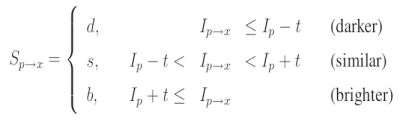

*Figure 2: https://docs.opencv.org/master/df/d0c/tutorial_py_fast.html*

If 12 contiguous pixels are either brighter or darker than the center pixel, then it is considered a feature.

A visualization showing the Bersham circle setup is shown below:

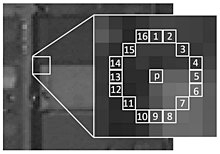

*Figure 1 (https://en.wikipedia.org/wiki/File:FAST_Corner_Detector.jpg)*

The actual implementation of the FAST algorithm is quite easy to implement, with the most difficult step being the Bresenham circle. An example implementation is seen below:

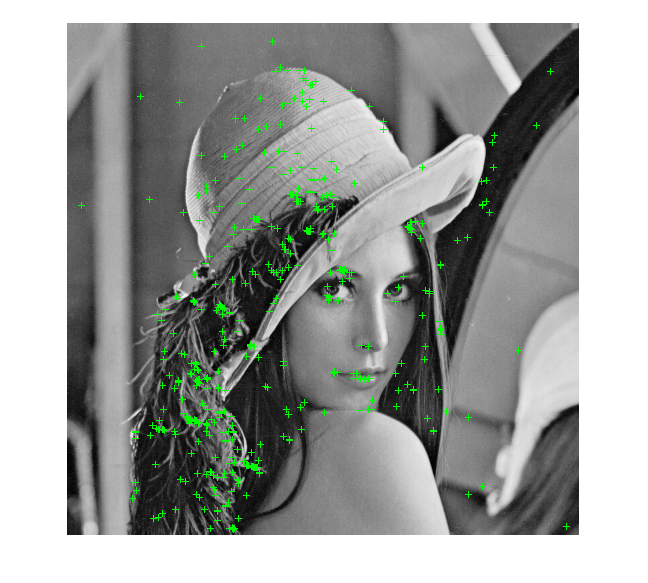

im=double(rgb2gray(imread('lena_std.tif')));
imSize = size(im);

%set the threshold between brighter and darker, as well as the radius of
%the Bresenham circle
threshold=2;
radius = 3;

%generate the Bresenham circle in the form of a matrix with offsets from
%the center pixel. (Code adapted from reference 5.)
[X,Y] = meshgrid(-radius:radius,-radius:radius);
distFromCenter = sqrt((X).^2 + (Y).^2);
onPixels = abs(distFromCenter-radius) < 0.5;

[yPx,xPx] = find(onPixels); 
yPx=yPx-radius;
xPx=xPx-radius;

%preallocate variable for storing if pixels are brighter or darker
circle_logic=zeros(radius+1^2,1);
%preallocate first feature so there is something to append to 
features=zeros([2,1]);

%create a Bresenham circle around each pixel and check if the conditions
%are met for it to be a corner, if yes add to features list
for center_x=radius+1:imSize(2)-(radius+1)
    for center_y=radius+1:imSize(1)-(radius+1)
        %get pixels around current pixel to check
        circle=im(sub2ind(size(im), center_y+yPx, center_x+xPx));
        
        for i=1:size(circle,1)
            
            %check brighter, darker conditions for pixels on circle
            if(circle(i)>im(center_y,center_x)+threshold)
                circle_logic(i)=1;
            elseif(circle(i)<im(center_y,center_x)-threshold)
                circle_logic(i)=-1;
            else
                circle_logic=0;
            end
        end
        
        %check if contigous pixels are all brighter or all darker
        
        longest_chain=1; %length of the longest chain
        temp_length=1; %the length of the current chain
        
        for i=1:size(circle_logic,2)-1
            if(circle_logic(i)==circle_logic(i+1) && circle_logic(i)~=0)
                temp_length=temp_length+1;
            else
                if(temp_length>longest_chain)
                    longest_chain=temp_length;
                end
                temp_length=1;
            end
        end
        %if the longest chain of pixels that are all brighter or all
        %darker, add to feature list
        if(longest_chain>=12)
            features(:,end+1)=[center_x;center_y];   
        end
   end
end

%Plotting
features(:,1)=[];
figure;
imshow(im,[]);
hold on
plot(features(1,:),features(2,:),'g+');

The code above has been deliberately coded as to be as verbose and easy to follow as possible, meaing that there is a large amount of optimization potential to truly maximzie performance. To examine the performance increase, we will use the built in Harris and FAST detector below.

Here performance improvement can be clearly seen. We time how long each step takes with the 'tic' and 'toc' command. You can run the following section several times, and although the exact time to run will change, notice that the FAST corner detection happens much more quickly. 


lena = imread('lena_std.tif');
lena_gray = double(rgb2gray(lena));

%The Harris Detector as covered in Lecture:
tic
checkers_rot_corners = uint16(detectHarrisFeatures(lena_gray).Location); 
toc

Elapsed time is 0.746481 seconds.



%The proposed solution, discussed further below
tic
checkers_rot_corners = uint16(detectFASTFeatures(lena_gray).Location); 
toc

Elapsed time is 0.146701 seconds.


The FAST algorithm is already pretty fast, requiring only 16 comparison operations compared to calculating a determinant of a matrix. It can be optimized further by not testing pixel 1, then pixel 2 and so on. Instead, pixels 1, 5, 9 and 13 are examined first. If 3 out of 4 of them do not meet either criteria 1) or 2) (from above) then the candidate cannot be a corner. If they do meet the corner criteria, the remaining pixels are investigated. This leads to a considerable speedup of testing images, but also means that the test is not quite as precise as it was before, especially because it can result in multiple features being detected adjacent to one another. This algorithm was one of the first that could identify corners in real time in a video stream, especially in 2006, when computing resources were not as plentiful as they are now. Further development has improved the precision of the method, even with the 4 pixel test, using machine learning. However, this potential source of error is not the largest drawback of the FAST algorithm. Both the Harris detector and the FAST algorithm are not scale invariant! This means that if a feature changes size, corners could either be detected where there were none before, or features that used to be seen as corners are not found anymore.

In this demonstration one can change the detector type and scaling factor to see how scaling an image effects the detected corners

scale=0.25;
detector="Harris";

pic= double(rgb2gray(imread('corner.jpg')));
scale_pic= imresize(pic,scale);

switch detector
    case "FAST"
        corners = uint16(detectFASTFeatures(pic).Location); 
        corners_scale = uint16(detectFASTFeatures(scale_pic).Location);
        
    case "Harris"
        corners = uint16(detectHarrisFeatures(pic).Location); 
        corners_scale = uint16(detectHarrisFeatures(scale_pic).Location);
        
end


figure
subplot(1,2,1)
imshow(pic);
title1=title('Original Image');
title1.FontSize=20;
hold on % show what comes next in the same subplot
scatter(corners(:,1),corners(:,2),'ro','filled');
subplot(1,2,2)

imshow(scale_pic,[]);
title2=title('Scaled Image');
title2.FontSize=20;
hold on
scatter(corners_scale(:,1),corners_scale(:,2),'ro','filled');

This scale invariance, as seen in the example above is probably the largest drawback to both the Harris Detector and the FAST algorithm. Especially if this is used in a stiuation where an agent is moving through the world, by moving further or closer to an object will change its scale, so this drawback is in practice a large problem. Given the large amount of applications of computer vision, a lot of research has been conducted on this, and as a result a lot of algorithms have been developed to deal with this, SURF and SIFT to name a few, but both of these are quite different to FAST and were also patented, so they are not available for general use. The ORB (Oriented FAST and Rotated BRIEF) algorithm was designed to be open-source, retain FAST's performance advantage, but addresses the scale invariance problem of FAST and significantly improves the feature description aspect. This side will not be covered here however.

ORB identifies features via the FAST algorithm, but then also stores copies of the image in a so called multiresoution image pyramid, where each level of the pyramid has a picture half as big as the level below it. That way, if the same scene is captured at a different scale, the ORB algorithm has some approximations to what it would look like, and can look for features at those approximated scales. 

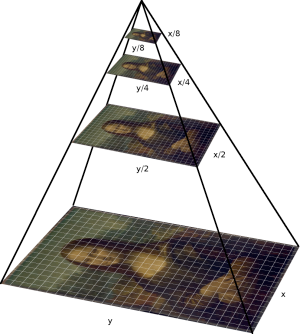

*Figure 3: A multiscale image pyramid https://medium.com/data-breach/introduction-to-orb-oriented-fast-and-rotated-brief-4220e8ec40cf*

This extension of the FAST algorithm turns out to be very good. "[It] performs as well as SIFT on the task of feature detection (and is  better than SURF) while being almost two orders of magnitude faster." (Source 4) It's open-source license means that it is also widely used, and included in OpenCV for example. Hopefully this demonstration has shed some light on how the algorithms work and what advantages and disadvantages they have. Thank you very much for reading.

Bibliography:

*1) Rosten, Edward; Tom Drummond (2005). *[*Fusing points and lines for high performance tracking*](http://edwardrosten.com/work/rosten_2005_tracking.pdf) *(PDF)**. **IEEE International Conference on Computer Vision**. ****2****. pp. 1508–1511. *[*CiteSeerX*](https://en.wikipedia.org/wiki/CiteSeerX_(identifier)) [*10.1.1.60.4715*](https://citeseerx.ist.psu.edu/viewdoc/summary?doi=10.1.1.60.4715)*. *[*doi*](https://en.wikipedia.org/wiki/Doi_(identifier))*:*[*10.1109/ICCV.2005.104*](https://doi.org/10.1109%2FICCV.2005.104)*. *[*ISBN*](https://en.wikipedia.org/wiki/ISBN_(identifier)) [*978-0-7695-2334-7*](https://en.wikipedia.org/wiki/Special:BookSources/978-0-7695-2334-7)*.*

2)  [https://docs.opencv.org/master/df/d0c/tutorial_py_fast.html](https://docs.opencv.org/master/df/d0c/tutorial_py_fast.html)

*3)* [https://en.wikipedia.org/wiki/Features_from_accelerated_segment_test](https://en.wikipedia.org/wiki/Features_from_accelerated_segment_test)

4)  [https://medium.com/data-breach/introduction-to-orb-oriented-fast-and-rotated-brief-4220e8ec40cf](https://medium.com/data-breach/introduction-to-orb-oriented-fast-and-rotated-brief-4220e8ec40cf) 

5) [https://de.mathworks.com/matlabcentral/answers/68067-pixel-position-of-circle-on-image](https://de.mathworks.com/matlabcentral/answers/68067-pixel-position-of-circle-on-image)